% Task 5
% Number of samples used for testing (number of elements of the data vector).
N =5000

N = 5000

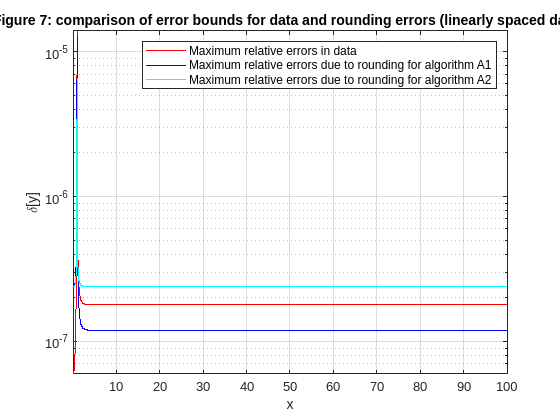

% initializing vectors of data:
% x:  vector of linearly spaced data values.
% xl: vector of logarithmically spaced data values.
x = linspace(10^-2, 10^2, N);
xl = logspace(-2, 2, N);

% Calculating the maximum relative error due to rounding.
epssin = eps("single")/2;

% Definition for coefficient of data error propogation derived in Task 1,
% coefficients of rounding error propogation in algorithm A1 (KA1) and in
% algorithm A2 (KA2) derived in Task 3.
T = @(x) ((x./(1+x.^2) -2*atan(x) -3*x.^5)./(atan(x)-x.^5) );
KA1 = @(x) 3*abs(1+x.^3./f(x))+abs(x.^3./f(x))+1;
KA2 = @(x) 3+abs(x.^3./f(x))+abs(atan(x)./(x.^2.*f(x)));

% Code for generation of figure 7
figure(7)
plot(x,abs(T(x)*epssin),"r-")
hold on;grid on;
axis([0.01,100,-inf,inf])
plot(x,(KA1(x)*epssin),"b-")
plot(x,(KA2(x)*epssin),"c-")
xlabel('x');
ylabel('\delta[y]');
title("Figure 7: comparison of error bounds for data and rounding errors (linearly spaced data):")
legend("Maximum relative errors in data","Maximum relative errors due to rounding for algorithm A1","Maximum relative errors due to rounding for algorithm A2")
yscale log;hold off;

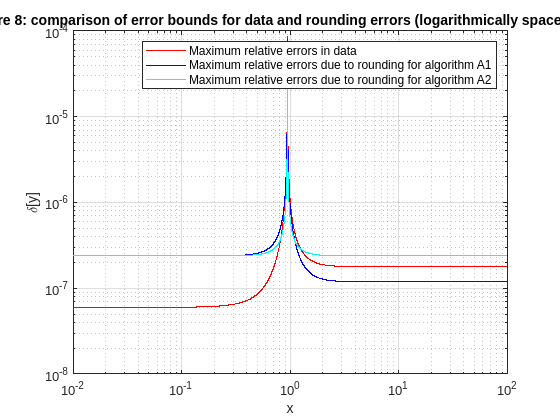


% Code for generation of figure 8
figure(8);
loglog(xl, abs(T(xl)*epssin), 'r-');
hold on;grid on;
loglog(xl, (KA1(xl)*epssin), 'b-');
loglog(xl, (KA2(xl)*epssin), 'c-');
xlabel('x');
ylabel('\delta[y]');
title("Figure 8: comparison of error bounds for data and rounding errors (logarithmically spaced data):")
legend("Maximum relative errors in data","Maximum relative errors due to rounding for algorithm A1","Maximum relative errors due to rounding for algorithm A2")
hold off;